## **Soft Manipulator Actuation** 

We created a 0.9m soft beam with radius linearly varying from 3cm to 1cm. The link consists of 2 divisions, the first division is 0.4m long and the second is 0.5m long.

All modes of deformation are enabled with a quadratic Legendre Polynomial parameterization

SorosimLink (`L1`) and SorosimLinkage (S`1`) are saved in `SoftManipulator.mat`

load('SoftManipulator.mat')

To see the properties of `L1`

L1

To see the properties of S`1`

S1

To see the problem definition:

S1.plotq0

The result should be:

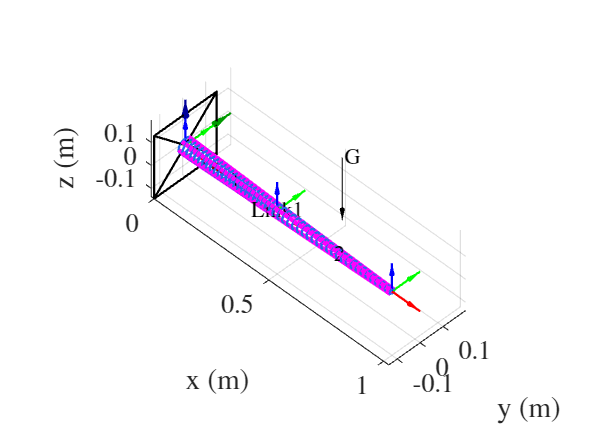

The beam is rigidly fixed at one end and can be subjected to actuation forces (6 oblique actuators).

### **Static equilibirum analysis**

For statics equilibirum analysis type:

q=S1.statics;

You will be prompted to enter the actuation force in the command window. Enter the input actuation forces into cables 1 and 2 respectively. eg: -50, -35, -10, -20, -40, -10.

A dialog box will then pop up, asking for the initial guess. The user can choose the default value.

The equilibirum solution is,

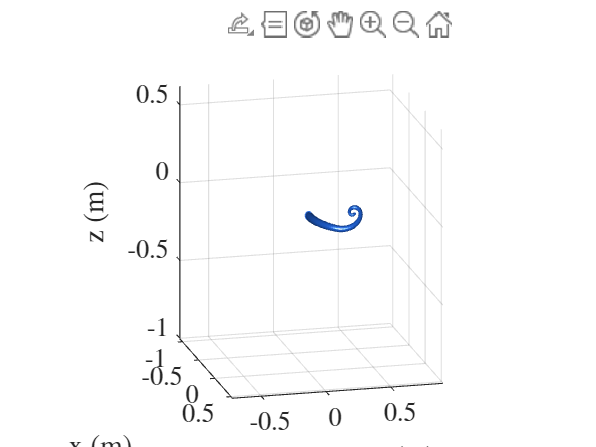

Alternatively you can run:

q = S1.statics([],[-20, -55, -10, -40, 0, -10]');

### **Dynamics**

For dynamics problem, type:

[t,qqd]=S1.dynamics([],@dynamicActionInputSM);

Modify the function dynamicActionInputSM.m to update the actuation input. If the function is not specified, the input can be given from the command window.

Initial conditions of state coordinates ($$\mathbf{q_0}$$) and their derivatives ($$\mathbf{\dot{q_0}}$$) will then be asked in a dialog box. The user can also choose the time for which the simulation is run (the default value is 5 s).

The results of the dynamic simulation (`t` and `qqd`) will be saved in `DynamicsSolution.mat `in the folder from which the simulation is run.

At the end of simulation, in the dialog box that appear, choose to generate the video if needed.  This step will take some time. 

A video named `Dynamics.mp4` will be saved in the folder.

Enable gravity and try again.

S1.Gravity=true;